if ~exist('binary_map','var')
    define_binary_map
end
lidar = rangeSensor("Range",[0 1], "HorizontalAngleResolution", 2*pi/90);

%  p_start = [1 1]
%  p_end = [7 8]

% p_start = rand_pt_in_map(binary_map_inflated);
% p_end = rand_pt_in_map(binary_map_inflated);
% pts = [p_start; p_end];

[ranges,angles] = lidar([p_start 0],binary_map);

T = 0.1; % Sampling period

robot_state = p_start;
poten = ctrl_potential();
poten.v_max = 1;
poten.k_goal = 10;
poten.avoidance_strength = 0.1;
poten.avoidance_distance = 0.1;
poten.robot_radius = 0.2;

N = 1e3

N = 1000


state_hist = NaN(N, 2);
u_hist = NaN(N, 2);

for i = 1:N
    state_hist(i,:) = robot_state;

    [ranges,angles] = lidar([robot_state 0],binary_map);
    v_xy = poten.step(robot_state, p_end, ranges, angles);
    u_hist(i,:) = v_xy;

    robot_state = robot_state + v_xy * T;

    if norm(robot_state - p_end) < 1e-2
        break
    end
end

disp("Time:" + i * T + " sec")

Time:100 sec


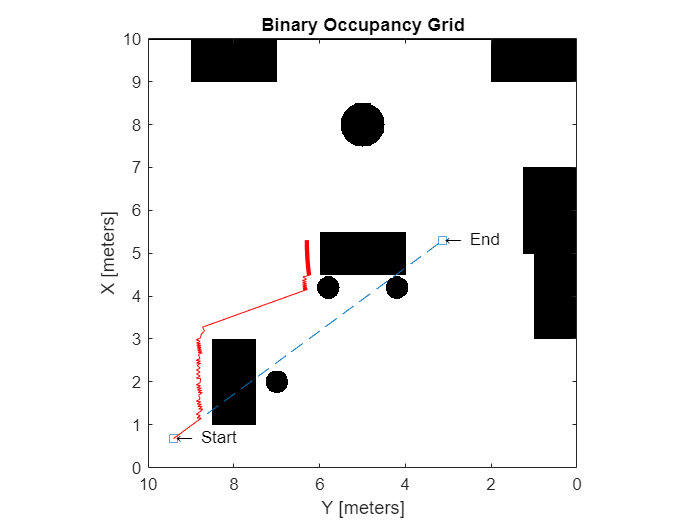


show(binary_map);
hold on
plot(pts(:,1), pts(:,2), '--s')
text(pts(1,1), pts(1,2), "\leftarrow Start")
text(pts(2,1), pts(2,2), "\leftarrow End")

plot(state_hist(:,1), state_hist(:,2), '-r')
hold off

%plot_scans(ranges, angles, [robot_state 0])

view(-90,90);

function plot_scans(ranges, angles, pose)
hold on

for i = 1:length(ranges)
    plot(pose(1)+[0 cos(pose(3)+angles(i))*ranges(i)], pose(2)+[0 sin(pose(3)+angles(i))*ranges(i)], 'k')
    
end

hold off
end